Robot1

L1(1) = Link('revolute','alpha',0,'a',0,'d',0.137,'offset',0,'modified');
L1(2) = Link('revolute','alpha',-pi/2,'a',0,'d',0,'offset',-pi/2,'modified');
L1(3) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');
L1(4) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');

R_tool = [0  0  1;
         -1  0  0;
          0 -1  0];
P_tool = [0.11 0 0]';
T_4_tool = rt2tr(R_tool,P_tool);
R1 = SerialLink(L1,'name','phantom1');
R1.tool = T_4_tool;
R1

 
R1 = 
 
phantom1 (4 axis, RRRR, modDH, slowRNE)                                        
                                                                               
+---+-----------+-----------+-----------+-----------+-----------+              
| j |     theta |         d |         a |     alpha |    offset |              
+---+-----------+-----------+-----------+-----------+-----------+              
|  1|         q1|      0.137|          0|          0|          0|              
|  2|         q2|          0|          0|     -1.571|     -1.571|              
|  3|         q3|          0|      0.105|          0|          0|              
|  4|         q4|          0|      0.105|          0|          0|              
+---+-----------+-----------+-----------+-----------+-----------+              
                                                                               
grav =    0  base = 1  0  0  0   tool =   0           0           1        0.11
          0         0  1  0  0

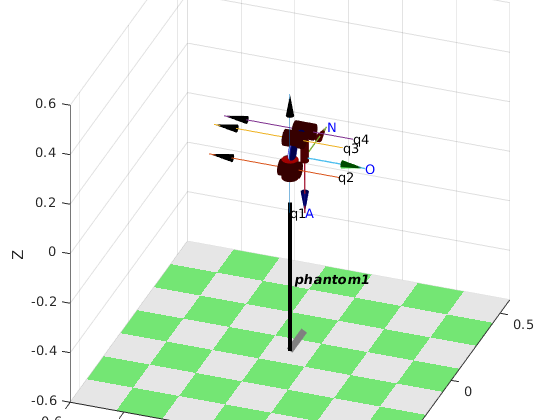




R1.plot([pi/2 0.4522 1.32 1.36],'noa','jvec','view',[20 30])

Robot2

L2(1) = Link('revolute','alpha',0,'a',0.5,'d',0.137,'offset',pi,'modified');
L2(2) = Link('revolute','alpha',-pi/2,'a',0,'d',0,'offset',-pi/2 ,'modified');
L2(3) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');
L2(4) = Link('revolute','alpha',0,'a',0.105,'d',0,'offset',0,'modified');

R_tool = [0  0  1;
         -1  0  0;
          0 -1  0];
P_tool = [0.11 0 0]';
T_4_tool = rt2tr(R_tool,P_tool);
R2 = SerialLink(L2,'name','phantom2');
R2.tool = T_4_tool;
R2

 
R2 = 
 
phantom2 (4 axis, RRRR, modDH, slowRNE)                                        
                                                                               
+---+-----------+-----------+-----------+-----------+-----------+              
| j |     theta |         d |         a |     alpha |    offset |              
+---+-----------+-----------+-----------+-----------+-----------+              
|  1|         q1|      0.137|        0.5|          0|      3.142|              
|  2|         q2|          0|          0|     -1.571|     -1.571|              
|  3|         q3|          0|      0.105|          0|          0|              
|  4|         q4|          0|      0.105|          0|          0|              
+---+-----------+-----------+-----------+-----------+-----------+              
                                                                               
grav =    0  base = 1  0  0  0   tool =   0           0           1        0.11
          0         0  1  0  0

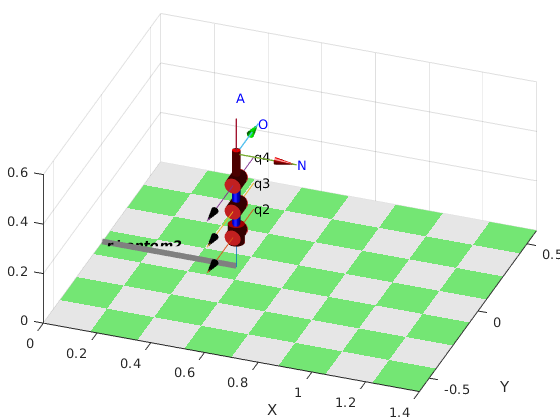




R2.plot([0 0 0 0],'workspace',[0 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

pic and place calculos

Primer punto

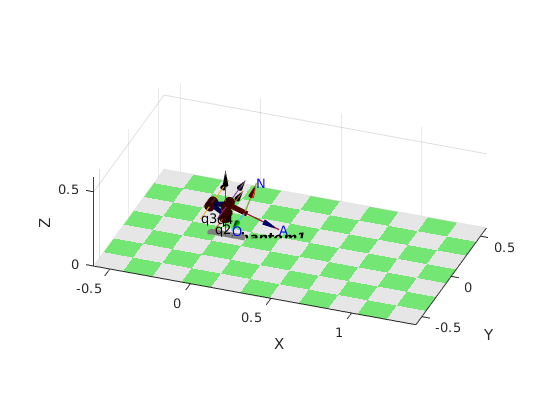

qi(1,:) =[0 -1 2.4 0.5 0 0];


R1.plot(qi(1,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Segundo punto

entrada_x=0.075;
entrada_y=0.065;
x = 0.053+entrada_x;
y = 0.040+entrada_y;

Punto_aprox = [1  0  0  x;
               0 -1  0  y;
               0  0 -1  0.1;
               0  0  0  1];
Rot = rotz(atan2(Punto_aprox(2,4),Punto_aprox(1,4)))*Punto_aprox(1:3,1:3);
MTH = rt2tr(Rot, Punto_aprox(1:3,4))

MTH =     0.7731    0.6342         0    0.1280
    0.6342   -0.7731         0    0.1050
         0         0   -1.0000    0.1000
         0         0         0    1.0000


qi(2,:) = [R1.ikunc(MTH,qi(1,1:4)) 0 0] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0


R1.fkine(qi(2,1:4))

ans =     0.7731    0.6342   -0.0000    0.1280
    0.6342   -0.7731   -0.0000    0.1050
   -0.0000   -0.0000   -1.0000    0.1000
         0         0         0    1.0000


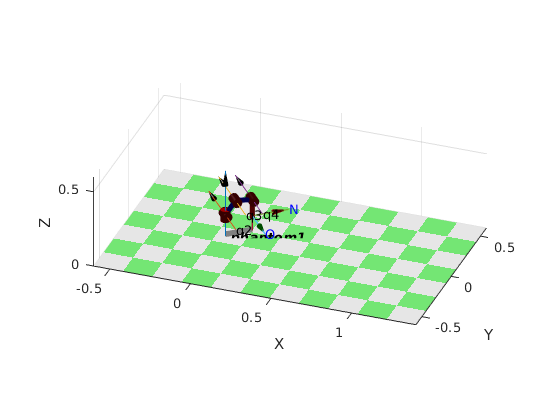

R1.plot(qi(2,1:4),'workspace',[-.05 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Tercer punto 



Punto_aprox = [1  0  0  x;
               0 -1  0  y;
               0  0 -1  0.03;
               0  0  0  1];
MTH = rt2tr(Rot, Punto_aprox(1:3,4))

MTH =     0.7731    0.6342         0    0.1280
    0.6342   -0.7731         0    0.1050
         0         0   -1.0000    0.0300
         0         0         0    1.0000


qi(3,:) = [R1.ikunc(MTH,qi(2,1:4)) 0 0] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0


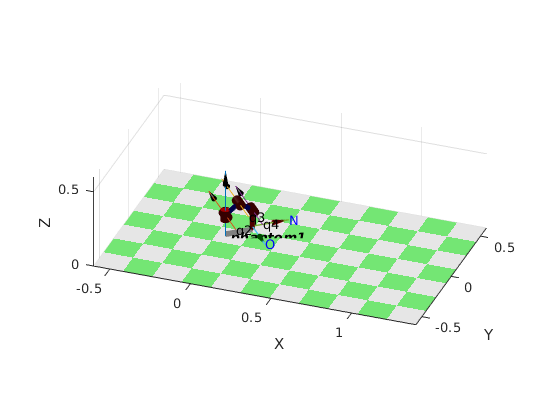

R1.plot(qi(3,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

qi(4,:) = [qi(3,1:4) 0.016 0.016];

Punto_aprox = [1  0  0  x;
               0 -1  0  y;
               0  0 -1  0.1;
               0  0  0  1];
MTH = rt2tr(Rot, Punto_aprox(1:3,4))

MTH =     0.7731    0.6342         0    0.1280
    0.6342   -0.7731         0    0.1050
         0         0   -1.0000    0.1000
         0         0         0    1.0000


qi(5,:) = [R1.ikunc(MTH,qi(4,1:4)) 0.016 0.016] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.6870    0.6231    1.0648    1.4537    0.0160    0.0160


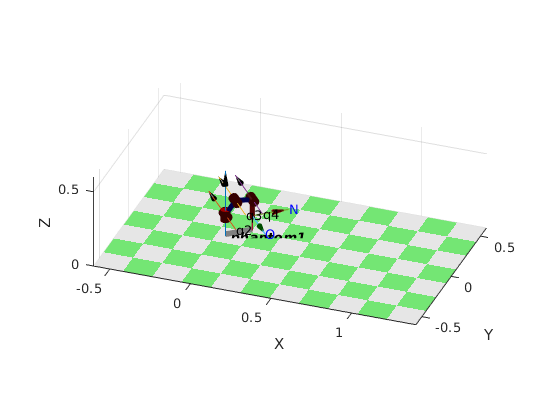

R1.plot(qi(5,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Punto_aprox = [1  0  0  0.128;
               0 -1  0 -0.156;
               0  0 -1  0.10;
               0  0  0  1];
Rot = rotz(atan2(Punto_aprox(2,4),Punto_aprox(1,4)))*Punto_aprox(1:3,1:3);
MTH = rt2tr(Rot, Punto_aprox(1:3,4))

MTH =     0.6343   -0.7731         0    0.1280
   -0.7731   -0.6343         0   -0.1560
         0         0   -1.0000    0.1000
         0         0         0    1.0000


qi(6,:) = [R1.ikunc(MTH,qi(5,1:4)) 0.016 0.016] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.6870    0.6231    1.0648    1.4537    0.0160    0.0160
   -0.8837    1.2215   -0.0000    1.9074    0.0160    0.0160


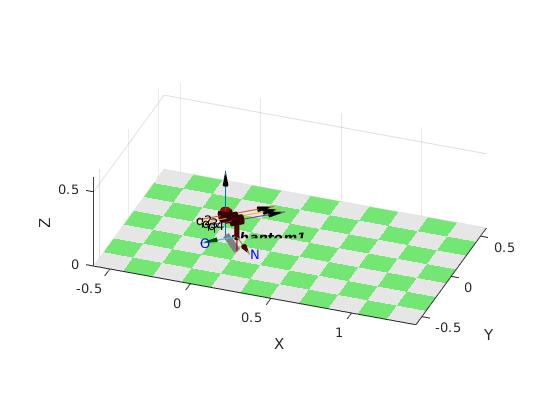

R1.plot(qi(6,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

Punto_aprox = [1  0  0  0.156;
               0 -1  0 -0.128;
               0  0 -1  0.03;
               0  0  0  1]

Punto_aprox =     1.0000         0         0    0.1560
         0   -1.0000         0   -0.1280
         0         0   -1.0000    0.0300
         0         0         0    1.0000


Rot = rotz(atan2(Punto_aprox(2,4),Punto_aprox(1,4)))*Punto_aprox(1:3,1:3);
MTH = rt2tr(Rot, Punto_aprox(1:3,4))

MTH =     0.7731   -0.6343         0    0.1560
   -0.6343   -0.7731         0   -0.1280
         0         0   -1.0000    0.0300
         0         0         0    1.0000


qi(7,:) = [R1.ikunc(MTH,qi(6,1:4)) 0.016 0.016] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.6870    0.6231    1.0648    1.4537    0.0160    0.0160
   -0.8837    1.2215   -0.0000    1.9074    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055    0.0160    0.0160


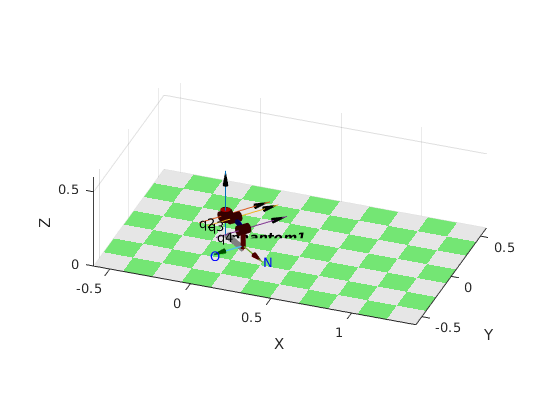

R1.plot(qi(7,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

qi(8,:) = [qi(7,1:4) 0 0];

Punto_aprox = [1  0  0  0.156;
               0 -1  0 -0.128;
               0  0 -1  0.1;
               0  0  0  1]

Punto_aprox =     1.0000         0         0    0.1560
         0   -1.0000         0   -0.1280
         0         0   -1.0000    0.1000
         0         0         0    1.0000


Rot = rotz(atan2(Punto_aprox(2,4),Punto_aprox(1,4)))*Punto_aprox(1:3,1:3);
MTH = rt2tr(Rot, Punto_aprox(1:3,4))

MTH =     0.7731   -0.6343         0    0.1560
   -0.6343   -0.7731         0   -0.1280
         0         0   -1.0000    0.1000
         0         0         0    1.0000


qi(9,:) = [R1.ikunc(MTH,qi(7,1:4)) 0 0] %llamamos la función

qi =          0   -1.0000    2.4000    0.5000         0         0
    0.6870    0.6231    1.0648    1.4537         0         0
    0.6870    0.8902    1.3249    0.9265         0         0
    0.6870    0.8902    1.3249    0.9265    0.0160    0.0160
    0.6870    0.6231    1.0648    1.4537    0.0160    0.0160
   -0.8837    1.2215   -0.0000    1.9074    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055    0.0160    0.0160
   -0.6871    1.2758    0.5603    1.3055         0         0
   -0.6871    1.2215    0.0000    1.9074         0         0


R1.plot(qi(8,1:4),'workspace',[-0.5 1.3 -0.5 0.5 0 0.6],'noa','jvec','view',[20 30])

qi(10,:) = qi(1,:);

rosinit

Initializing global node /matlab_global_node_65696 with NodeURI http://cristian-X555QG:38843/


phantompos = rospublisher('/robot_1/phantom_position_controller/command');
message = rosmessage(phantompos)

message =   ROS Float64MultiArray message with properties:

    MessageType: 'std_msgs/Float64MultiArray'
         Layout: [1×1 MultiArrayLayout]
           Data: [0×1 double]

  Use showdetails to show the contents of the message


states =          0   -0.0300    0.0300    0.0300         0         0


states =          0   -0.1100    0.1100    0.1100         0         0


states =          0   -0.1400    0.1400    0.1400         0         0


states =          0   -0.1700    0.1700    0.1700         0         0


states =          0   -0.1900    0.1900    0.1900         0         0


states =          0   -0.2200    0.2200    0.2200         0         0


states =          0   -0.2500    0.2500    0.2500         0         0


states =          0   -0.2700    0.2700    0.2700         0         0


states =          0   -0.2800    0.2800    0.2800         0         0


states =          0   -0.2900    0.2900    0.2900         0         0


states =          0   -0.3000    0.3000    0.3000         0         0


states =          0   -0.3200    0.3200    0.3200         0         0


states =          0   -0.3400    0.3400    0.3400         0         0


states =          0   -0.3600    0.3600    0.3600         0         0


states =          0   -0.3800    0.3800    0.3800         0         0


states =          0   -0.4000    0.4000    0.4000         0         0


states =          0   -0.4200    0.4200    0.4200         0         0


states =          0   -0.4600    0.4600    0.4600         0         0


states =          0   -0.5000    0.5000    0.5000         0         0


states =          0   -0.5300    0.5300    0.5000         0         0


states =          0   -0.5600    0.5600    0.5000         0         0


states =          0   -0.6000    0.6000    0.5000         0         0


states =          0   -0.6100    0.6100    0.5000         0         0


states =          0   -0.6200    0.6200    0.5000         0         0


states =          0   -0.6300    0.6300    0.5000         0         0


states =          0   -0.6500    0.6500    0.5000         0         0


states =          0   -0.6600    0.6600    0.5000         0         0


states =          0   -0.6800    0.6800    0.5000         0         0


states =          0   -0.6900    0.6900    0.5000         0         0


states =          0   -0.7000    0.7000    0.5000         0         0


states =          0   -0.7300    0.7300    0.5000         0         0


states =          0   -0.7500    0.7500    0.5000         0         0


states =          0   -0.7700    0.7700    0.5000         0         0


states =          0   -0.7800    0.7800    0.5000         0         0


states =          0   -0.8000    0.8000    0.5000         0         0


states = 1×6
         0   -0.8100    0.8100    0.5000         0         0


states = 1×6
         0   -0.8300    0.8300    0.5000         0         0


states = 1×6
         0   -0.8500    0.8500    0.5000         0         0


states = 1×6
         0   -0.8700    0.8700    0.5000         0         0


states = 1×6
         0   -0.8800    0.8800    0.5000         0         0


states = 1×6
         0   -0.9000    0.9000    0.5000         0         0


states = 1×6
         0   -0.9100    0.9100    0.5000         0         0


states = 1×6
         0   -0.9300    0.9300    0.5000         0         0


states = 1×6
         0   -0.9500    0.9500    0.5000         0         0


states = 1×6
         0   -0.9700    0.9700    0.5000         0         0


states = 1×6
         0   -0.9800    0.9800    0.5000         0         0


states = 1×6
         0   -0.9900    0.9900    0.5000         0         0


states = 1×6
         0   -1.0000    1.0000    0.5000         0         0


states = 1×6
         0   -1.0000    1.0100    0.5000         0         0


states = 1×6
         0   -1.0000    1.0200    0.5000         0         0


states = 1×6
         0   -1.0000    1.0300    0.5000         0         0


states = 1×6
         0   -1.0000    1.0400    0.5000         0         0


states = 1×6
         0   -1.0000    1.0500    0.5000         0         0


states = 1×6
         0   -1.0000    1.0600    0.5000         0         0


states = 1×6
         0   -1.0000    1.0700    0.5000         0         0


states = 1×6
         0   -1.0000    1.0800    0.5000         0         0


states = 1×6
         0   -1.0000    1.1000    0.5000         0         0


states = 1×6
         0   -1.0000    1.1300    0.5000         0         0


states = 1×6
         0   -1.0000    1.1500    0.5000         0         0


states = 1×6
         0   -1.0000    1.1600    0.5000         0         0


states = 1×6
         0   -1.0000    1.1700    0.5000         0         0


states = 1×6
         0   -1.0000    1.1800    0.5000         0         0


states = 1×6
         0   -1.0000    1.2000    0.5000         0         0


states = 1×6
         0   -1.0000    1.2100    0.5000         0         0


states = 1×6
         0   -1.0000    1.2200    0.5000         0         0


states = 1×6
         0   -1.0000    1.2300    0.5000         0         0


states = 1×6
         0   -1.0000    1.2400    0.5000         0         0


states = 1×6
         0   -1.0000    1.2600    0.5000         0         0


states = 1×6
         0   -1.0000    1.2700    0.5000         0         0


states = 1×6
         0   -1.0000    1.2900    0.5000         0         0


states = 1×6
         0   -1.0000    1.3100    0.5000         0         0


states = 1×6
         0   -1.0000    1.3300    0.5000         0         0


states = 1×6
         0   -1.0000    1.3400    0.5000         0         0


states = 1×6
         0   -1.0000    1.3600    0.5000         0         0


states = 1×6
         0   -1.0000    1.3800    0.5000         0         0


states = 1×6
         0   -1.0000    1.3900    0.5000         0         0


states = 1×6
         0   -1.0000    1.4000    0.5000         0         0


states = 1×6
         0   -1.0000    1.4200    0.5000         0         0


states = 1×6
         0   -1.0000    1.4300    0.5000         0         0


states = 1×6
         0   -1.0000    1.4400    0.5000         0         0


states = 1×6
         0   -1.0000    1.4500    0.5000         0         0


states = 1×6
         0   -1.0000    1.4600    0.5000         0         0


states = 1×6
         0   -1.0000    1.4800    0.5000         0         0


states = 1×6
         0   -1.0000    1.4900    0.5000         0         0


states = 1×6
         0   -1.0000    1.5100    0.5000         0         0


states = 1×6
         0   -1.0000    1.5300    0.5000         0         0


states = 1×6
         0   -1.0000    1.5400    0.5000         0         0


states = 1×6
         0   -1.0000    1.5600    0.5000         0         0


states = 1×6
         0   -1.0000    1.5700    0.5000         0         0


states = 1×6
         0   -1.0000    1.5800    0.5000         0         0


states = 1×6
         0   -1.0000    1.5900    0.5000         0         0


states = 1×6
         0   -1.0000    1.6100    0.5000         0         0


states = 1×6
         0   -1.0000    1.6300    0.5000         0         0


states = 1×6
         0   -1.0000    1.6400    0.5000         0         0


states = 1×6
         0   -1.0000    1.6600    0.5000         0         0


states = 1×6
         0   -1.0000    1.6900    0.5000         0         0


states = 1×6
         0   -1.0000    1.7100    0.5000         0         0


states = 1×6
         0   -1.0000    1.7200    0.5000         0         0


states = 1×6
         0   -1.0000    1.7400    0.5000         0         0


states = 1×6
         0   -1.0000    1.7500    0.5000         0         0


states = 1×6
         0   -1.0000    1.7600    0.5000         0         0


states = 1×6
         0   -1.0000    1.7800    0.5000         0         0


states = 1×6
         0   -1.0000    1.8000    0.5000         0         0


states = 1×6
         0   -1.0000    1.8100    0.5000         0         0


states = 1×6
         0   -1.0000    1.8200    0.5000         0         0


states = 1×6
         0   -1.0000    1.8300    0.5000         0         0


states = 1×6
         0   -1.0000    1.8400    0.5000         0         0


states = 1×6
         0   -1.0000    1.8600    0.5000         0         0


states = 1×6
         0   -1.0000    1.8700    0.5000         0         0


states = 1×6
         0   -1.0000    1.8800    0.5000         0         0


states = 1×6
         0   -1.0000    1.8900    0.5000         0         0


states = 1×6
         0   -1.0000    1.9000    0.5000         0         0


states = 1×6
         0   -1.0000    1.9100    0.5000         0         0


states = 1×6
         0   -1.0000    1.9200    0.5000         0         0


states = 1×6
         0   -1.0000    1.9300    0.5000         0         0


states = 1×6
         0   -1.0000    1.9400    0.5000         0         0


states = 1×6
         0   -1.0000    1.9500    0.5000         0         0


states = 1×6
         0   -1.0000    1.9600    0.5000         0         0


states = 1×6
         0   -1.0000    1.9800    0.5000         0         0


states = 1×6
         0   -1.0000    1.9900    0.5000         0         0


states = 1×6
         0   -1.0000    2.0000    0.5000         0         0


states = 1×6
         0   -1.0000    2.0200    0.5000         0         0


states = 1×6
         0   -1.0000    2.0300    0.5000         0         0


states = 1×6
         0   -1.0000    2.0400    0.5000         0         0


states = 1×6
         0   -1.0000    2.0500    0.5000         0         0


states = 1×6
         0   -1.0000    2.0600    0.5000         0         0


states = 1×6
         0   -1.0000    2.0800    0.5000         0         0


states = 1×6
         0   -1.0000    2.1000    0.5000         0         0


states = 1×6
         0   -1.0000    2.1100    0.5000         0         0


states = 1×6
         0   -1.0000    2.1200    0.5000         0         0


states = 1×6
         0   -1.0000    2.1300    0.5000         0         0


states = 1×6
         0   -1.0000    2.1400    0.5000         0         0


states = 1×6
         0   -1.0000    2.1600    0.5000         0         0


states = 1×6
         0   -1.0000    2.1700    0.5000         0         0


states = 1×6
         0   -1.0000    2.1800    0.5000         0         0


states = 1×6
         0   -1.0000    2.2000    0.5000         0         0


states = 1×6
         0   -1.0000    2.2100    0.5000         0         0


states = 1×6
         0   -1.0000    2.2200    0.5000         0         0


states = 1×6
         0   -1.0000    2.2300    0.5000         0         0


states = 1×6
         0   -1.0000    2.2500    0.5000         0         0


states = 1×6
         0   -1.0000    2.2600    0.5000         0         0


states = 1×6
         0   -1.0000    2.2700    0.5000         0         0


states = 1×6
         0   -1.0000    2.3000    0.5000         0         0


states = 1×6
         0   -1.0000    2.3200    0.5000         0         0


states = 1×6
         0   -1.0000    2.3300    0.5000         0         0


states = 1×6
         0   -1.0000    2.3400    0.5000         0         0


states = 1×6
         0   -1.0000    2.3500    0.5000         0         0


states = 1×6
         0   -1.0000    2.3600    0.5000         0         0


states = 1×6
         0   -1.0000    2.3700    0.5000         0         0


states = 1×6
         0   -1.0000    2.3800    0.5000         0         0


states = 1×6
         0   -1.0000    2.3900    0.5000         0         0


states = 1×6
         0   -1.0000    2.4000    0.5000         0         0


states = 1×6
         0   -1.0000    2.4000    0.5000         0         0


states = 1×6
    0.0100   -0.9900    2.3900    0.5100         0         0


states = 1×6
    0.0200   -0.9800    2.3800    0.5200         0         0


states = 1×6
    0.0300   -0.9700    2.3700    0.5300         0         0


states = 1×6
    0.0400   -0.9600    2.3600    0.5400         0         0


states = 1×6
    0.0500   -0.9500    2.3500    0.5500         0         0


states = 1×6
    0.0600   -0.9400    2.3400    0.5600         0         0


states = 1×6
    0.0700   -0.9300    2.3300    0.5700         0         0


states = 1×6
    0.0800   -0.9200    2.3200    0.5800         0         0


states = 1×6
    0.0900   -0.9100    2.3100    0.5900         0         0


states = 1×6
    0.1000   -0.9000    2.3000    0.6000         0         0


states = 1×6
    0.1100   -0.8900    2.2900    0.6100         0         0


states = 1×6
    0.1200   -0.8800    2.2800    0.6200         0         0


states = 1×6
    0.1300   -0.8700    2.2700    0.6300         0         0


states = 1×6
    0.1400   -0.8600    2.2600    0.6400         0         0


states = 1×6
    0.1500   -0.8500    2.2500    0.6500         0         0


states = 1×6
    0.1600   -0.8400    2.2400    0.6600         0         0


states = 1×6
    0.1700   -0.8300    2.2300    0.6700         0         0


states = 1×6
    0.1800   -0.8200    2.2200    0.6800         0         0


states = 1×6
    0.1900   -0.8100    2.2100    0.6900         0         0


states = 1×6
    0.2000   -0.8000    2.2000    0.7000         0         0


states = 1×6
    0.2200   -0.7800    2.1800    0.7200         0         0


states = 1×6
    0.2300   -0.7700    2.1700    0.7300         0         0


states = 1×6
    0.2400   -0.7600    2.1600    0.7400         0         0


states = 1×6
    0.2500   -0.7500    2.1500    0.7500         0         0


states = 1×6
    0.2600   -0.7400    2.1400    0.7600         0         0


states = 1×6
    0.2700   -0.7300    2.1300    0.7700         0         0


states = 1×6
    0.2800   -0.7200    2.1200    0.7800         0         0


states = 1×6
    0.2900   -0.7100    2.1100    0.7900         0         0


states = 1×6
    0.3000   -0.7000    2.1000    0.8000         0         0


states = 1×6
    0.3100   -0.6900    2.0900    0.8100         0         0


states = 1×6
    0.3200   -0.6800    2.0800    0.8200         0         0


states = 1×6
    0.3300   -0.6700    2.0700    0.8300         0         0


states = 1×6
    0.3400   -0.6600    2.0600    0.8400         0         0


states = 1×6
    0.3500   -0.6500    2.0500    0.8500         0         0


states = 1×6
    0.3600   -0.6400    2.0400    0.8600         0         0


states = 1×6
    0.3700   -0.6300    2.0300    0.8700         0         0


states = 1×6
    0.3800   -0.6200    2.0200    0.8800         0         0


states = 1×6
    0.3900   -0.6100    2.0100    0.8900         0         0


states = 1×6
    0.4000   -0.6000    2.0000    0.9000         0         0


states = 1×6
    0.4100   -0.5900    1.9900    0.9100         0         0


states = 1×6
    0.4200   -0.5800    1.9800    0.9200         0         0


states = 1×6
    0.4300   -0.5700    1.9700    0.9300         0         0


states = 1×6
    0.4400   -0.5600    1.9600    0.9400         0         0


states = 1×6
    0.4500   -0.5500    1.9500    0.9500         0         0


states = 1×6
    0.4600   -0.5400    1.9400    0.9600         0         0


states = 1×6
    0.4700   -0.5300    1.9300    0.9700         0         0


states = 1×6
    0.4800   -0.5200    1.9200    0.9800         0         0


states = 1×6
    0.5000   -0.5000    1.9000    1.0000         0         0


states = 1×6
    0.5100   -0.4900    1.8900    1.0100         0         0


states = 1×6
    0.5200   -0.4800    1.8800    1.0200         0         0


states = 1×6
    0.5300   -0.4700    1.8700    1.0300         0         0


states = 1×6
    0.5400   -0.4600    1.8600    1.0400         0         0


states = 1×6
    0.5500   -0.4500    1.8500    1.0500         0         0


states = 1×6
    0.5700   -0.4300    1.8300    1.0700         0         0


states = 1×6
    0.5800   -0.4200    1.8200    1.0800         0         0


states = 1×6
    0.5900   -0.4100    1.8100    1.0900         0         0


states = 1×6
    0.6000   -0.4000    1.8000    1.1000         0         0


states = 1×6
    0.6100   -0.3900    1.7900    1.1100         0         0


states = 1×6
    0.6200   -0.3800    1.7800    1.1200         0         0


states = 1×6
    0.6300   -0.3700    1.7700    1.1300         0         0


states = 1×6
    0.6400   -0.3600    1.7600    1.1400         0         0


states = 1×6
    0.6500   -0.3500    1.7500    1.1500         0         0


states = 1×6
    0.6600   -0.3400    1.7400    1.1600         0         0


states = 1×6
    0.6700   -0.3300    1.7300    1.1700         0         0


states = 1×6
    0.6800   -0.3200    1.7200    1.1800         0         0


states = 1×6
    0.6900   -0.3100    1.7100    1.1900         0         0


states = 1×6
    0.6900   -0.3000    1.7000    1.2000         0         0


states = 1×6
    0.6900   -0.2900    1.6900    1.2100         0         0


states = 1×6
    0.6900   -0.2800    1.6800    1.2200         0         0


states = 1×6
    0.6900   -0.2700    1.6700    1.2300         0         0


states = 1×6
    0.6900   -0.2600    1.6600    1.2400         0         0


states = 1×6
    0.6900   -0.2500    1.6500    1.2500         0         0


states = 1×6
    0.6900   -0.2400    1.6400    1.2600         0         0


states = 1×6
    0.6900   -0.2300    1.6300    1.2700         0         0


states = 1×6
    0.6900   -0.2200    1.6200    1.2800         0         0


states = 1×6
    0.6900   -0.2100    1.6100    1.2900         0         0


states = 1×6
    0.6900   -0.2000    1.6000    1.3000         0         0


states = 1×6
    0.6900   -0.1900    1.5900    1.3100         0         0


states = 1×6
    0.6900   -0.1800    1.5800    1.3200         0         0


states = 1×6
    0.6900   -0.1700    1.5700    1.3300         0         0


states = 1×6
    0.6900   -0.1600    1.5600    1.3400         0         0


states = 1×6
    0.6900   -0.1500    1.5500    1.3500         0         0


states = 1×6
    0.6900   -0.1400    1.5400    1.3600         0         0


states = 1×6
    0.6900   -0.1300    1.5300    1.3700         0         0


states = 1×6
    0.6900   -0.1200    1.5200    1.3800         0         0


states = 1×6
    0.6900   -0.1100    1.5100    1.3900         0         0


states = 1×6
    0.6900   -0.1000    1.5000    1.4000         0         0


states = 1×6
    0.6900   -0.0900    1.4900    1.4100         0         0


states = 1×6
    0.6900   -0.0800    1.4800    1.4200         0         0


states = 1×6
    0.6900   -0.0700    1.4700    1.4300         0         0


states = 1×6
    0.6900   -0.0600    1.4600    1.4400         0         0


states = 1×6
    0.6900   -0.0500    1.4500    1.4500         0         0


states = 1×6
    0.6900   -0.0400    1.4400    1.4500         0         0


states = 1×6
    0.6900   -0.0300    1.4300    1.4500         0         0


states = 1×6
    0.6900   -0.0200    1.4200    1.4500         0         0


states = 1×6
    0.6900   -0.0100    1.4100    1.4500         0         0


states = 1×6
    0.6900         0    1.4000    1.4500         0         0


states = 1×6
    0.6900    0.0100    1.3900    1.4500         0         0


states = 1×6
    0.6900    0.0200    1.3800    1.4500         0         0


states = 1×6
    0.6900    0.0300    1.3700    1.4500         0         0


states = 1×6
    0.6900    0.0400    1.3600    1.4500         0         0


states = 1×6
    0.6900    0.0500    1.3500    1.4500         0         0


states = 1×6
    0.6900    0.0600    1.3400    1.4500         0         0


states = 1×6
    0.6900    0.0700    1.3300    1.4500         0         0


states = 1×6
    0.6900    0.0800    1.3200    1.4500         0         0


states = 1×6
    0.6900    0.0900    1.3100    1.4500         0         0


states = 1×6
    0.6900    0.1000    1.3000    1.4500         0         0


states = 1×6
    0.6900    0.1100    1.2900    1.4500         0         0


states = 1×6
    0.6900    0.1200    1.2800    1.4500         0         0


states = 1×6
    0.6900    0.1300    1.2700    1.4500         0         0


states = 1×6
    0.6900    0.1400    1.2600    1.4500         0         0


states = 1×6
    0.6900    0.1500    1.2500    1.4500         0         0


states = 1×6
    0.6900    0.1600    1.2400    1.4500         0         0


states = 1×6
    0.6900    0.1700    1.2300    1.4500         0         0


states = 1×6
    0.6900    0.1800    1.2200    1.4500         0         0


states = 1×6
    0.6900    0.1900    1.2100    1.4500         0         0


states = 1×6
    0.6900    0.2000    1.2000    1.4500         0         0


states = 1×6
    0.6900    0.2100    1.1900    1.4500         0         0


states = 1×6
    0.6900    0.2200    1.1800    1.4500         0         0


states = 1×6
    0.6900    0.2300    1.1700    1.4500         0         0


states = 1×6
    0.6900    0.2400    1.1600    1.4500         0         0


states = 1×6
    0.6900    0.2500    1.1500    1.4500         0         0


states = 1×6
    0.6900    0.2600    1.1400    1.4500         0         0


states = 1×6
    0.6900    0.2700    1.1300    1.4500         0         0


states = 1×6
    0.6900    0.2900    1.1100    1.4500         0         0


states = 1×6
    0.6900    0.3000    1.1000    1.4500         0         0


states = 1×6
    0.6900    0.3100    1.0900    1.4500         0         0


states = 1×6
    0.6900    0.3200    1.0800    1.4500         0         0


states = 1×6
    0.6900    0.3300    1.0700    1.4500         0         0


states = 1×6
    0.6900    0.3400    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.3500    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.3600    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.3700    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.3800    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.3900    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.4000    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.4100    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.4300    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.4500    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.4600    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.4700    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.4800    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.4900    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5000    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5100    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5200    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5300    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5400    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5500    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5600    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5700    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5800    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.5900    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.6000    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.6100    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.6200    1.0600    1.4500         0         0


states = 1×6
    0.6900    0.6300    1.0700    1.4400         0         0


states = 1×6
    0.6900    0.6400    1.0800    1.4300         0         0


states = 1×6
    0.6900    0.6500    1.0900    1.4200         0         0


states = 1×6
    0.6900    0.6600    1.1000    1.4100         0         0


states = 1×6
    0.6900    0.6700    1.1100    1.4000         0         0


states = 1×6
    0.6900    0.6800    1.1200    1.3900         0         0


states = 1×6
    0.6900    0.6900    1.1300    1.3800         0         0


states = 1×6
    0.6900    0.7000    1.1400    1.3700         0         0


states = 1×6
    0.6900    0.7100    1.1500    1.3600         0         0


states = 1×6
    0.6900    0.7200    1.1600    1.3500         0         0


states = 1×6
    0.6900    0.7300    1.1700    1.3400         0         0


states = 1×6
    0.6900    0.7400    1.1800    1.3300         0         0


states = 1×6
    0.6900    0.7500    1.1900    1.3200         0         0


states = 1×6
    0.6900    0.7600    1.2000    1.3100         0         0


states = 1×6
    0.6900    0.7700    1.2100    1.3000         0         0


states = 1×6
    0.6900    0.7800    1.2200    1.2900         0         0


states = 1×6
    0.6900    0.7900    1.2300    1.2800         0         0


states = 1×6
    0.6900    0.8000    1.2400    1.2700         0         0


states = 1×6
    0.6900    0.8100    1.2500    1.2600         0         0


states = 1×6
    0.6900    0.8200    1.2600    1.2500         0         0


states = 1×6
    0.6900    0.8300    1.2700    1.2400         0         0


states = 1×6
    0.6900    0.8400    1.2800    1.2300         0         0


states = 1×6
    0.6900    0.8500    1.2900    1.2200         0         0


states = 1×6
    0.6900    0.8600    1.3000    1.2100         0         0


states = 1×6
    0.6900    0.8700    1.3100    1.2000         0         0


states = 1×6
    0.6900    0.8800    1.3200    1.1900         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.1800         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.1700         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.1600         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.1500         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.1400         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.1300         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.1200         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.1000         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0900         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0800         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0700         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0600         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0500         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0400         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0300         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0200         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0100         0         0


states = 1×6
    0.6900    0.8900    1.3200    1.0000         0         0


states = 1×6
    0.6900    0.8900    1.3200    0.9900         0         0


states = 1×6
    0.6900    0.8900    1.3200    0.9800         0         0


states = 1×6
    0.6900    0.8900    1.3200    0.9700         0         0


states = 1×6
    0.6900    0.8900    1.3200    0.9600         0         0


states = 1×6
    0.6900    0.8900    1.3200    0.9500         0         0


states = 1×6
    0.6900    0.8900    1.3200    0.9400         0         0


states = 1×6
    0.6900    0.8900    1.3200    0.9300         0         0


states = 1×6
    0.6900    0.8900    1.3200    0.9300         0         0


states = 1×6
    0.6900    0.8900    1.3200    0.9300    0.0100    0.0100


states = 1×6
    0.6900    0.8900    1.3200    0.9300    0.0200    0.0200


states = 1×6
    0.6900    0.8900    1.3200    0.9300    0.0200    0.0200


states = 1×6
    0.6900    0.8800    1.3100    0.9400    0.0200    0.0200


states = 1×6
    0.6900    0.8700    1.3000    0.9500    0.0200    0.0200


states = 1×6
    0.6900    0.8600    1.2900    0.9600    0.0200    0.0200


states = 1×6
    0.6900    0.8500    1.2800    0.9700    0.0200    0.0200


states = 1×6
    0.6900    0.8400    1.2700    0.9800    0.0200    0.0200


states = 1×6
    0.6900    0.8300    1.2600    0.9900    0.0200    0.0200


states = 1×6
    0.6900    0.8200    1.2500    1.0000    0.0200    0.0200


states = 1×6
    0.6900    0.8100    1.2400    1.0100    0.0200    0.0200


states = 1×6
    0.6900    0.8000    1.2300    1.0200    0.0200    0.0200


states = 1×6
    0.6900    0.7900    1.2200    1.0300    0.0200    0.0200


states = 1×6
    0.6900    0.7800    1.2100    1.0400    0.0200    0.0200


states = 1×6
    0.6900    0.7700    1.2000    1.0500    0.0200    0.0200


states = 1×6
    0.6900    0.7600    1.1900    1.0600    0.0200    0.0200


states = 1×6
    0.6900    0.7500    1.1800    1.0700    0.0200    0.0200


states = 1×6
    0.6900    0.7400    1.1700    1.0800    0.0200    0.0200


states = 1×6
    0.6900    0.7300    1.1600    1.0900    0.0200    0.0200


states = 1×6
    0.6900    0.7200    1.1500    1.1000    0.0200    0.0200


states = 1×6
    0.6900    0.7100    1.1400    1.1100    0.0200    0.0200


states = 1×6
    0.6900    0.7000    1.1300    1.1200    0.0200    0.0200


states = 1×6
    0.6900    0.6900    1.1200    1.1300    0.0200    0.0200


states = 1×6
    0.6900    0.6800    1.1100    1.1400    0.0200    0.0200


states = 1×6
    0.6900    0.6700    1.1000    1.1500    0.0200    0.0200


states = 1×6
    0.6900    0.6600    1.0900    1.1600    0.0200    0.0200


states = 1×6
    0.6900    0.6400    1.0700    1.1800    0.0200    0.0200


states = 1×6
    0.6900    0.6300    1.0600    1.1900    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2000    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2100    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2200    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2300    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2400    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2500    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2600    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2700    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2800    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.2900    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3000    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3100    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3200    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3300    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3400    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3500    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3600    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3700    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3800    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.3900    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.4000    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.4100    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.4200    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.4300    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.4400    0.0200    0.0200


states = 1×6
    0.6900    0.6200    1.0600    1.4500    0.0200    0.0200


states = 1×6
    0.6800    0.6300    1.0600    1.4600    0.0200    0.0200


states = 1×6
    0.6700    0.6400    1.0500    1.4700    0.0200    0.0200


states = 1×6
    0.6600    0.6500    1.0400    1.4800    0.0200    0.0200


states = 1×6
    0.6500    0.6600    1.0300    1.4900    0.0200    0.0200


states = 1×6
    0.6400    0.6700    1.0200    1.5000    0.0200    0.0200


states = 1×6
    0.6300    0.6800    1.0100    1.5100    0.0200    0.0200


states = 1×6
    0.6200    0.6900    1.0000    1.5200    0.0200    0.0200


states = 1×6
    0.6100    0.7000    0.9900    1.5300    0.0200    0.0200


states = 1×6
    0.6000    0.7100    0.9800    1.5400    0.0200    0.0200


states = 1×6
    0.5900    0.7200    0.9700    1.5500    0.0200    0.0200


states = 1×6
    0.5800    0.7300    0.9600    1.5600    0.0200    0.0200


states = 1×6
    0.5700    0.7400    0.9500    1.5700    0.0200    0.0200


states = 1×6
    0.5600    0.7500    0.9400    1.5800    0.0200    0.0200


states = 1×6
    0.5500    0.7600    0.9300    1.5900    0.0200    0.0200


states = 1×6
    0.5400    0.7700    0.9200    1.6000    0.0200    0.0200


states = 1×6
    0.5300    0.7800    0.9100    1.6100    0.0200    0.0200


states = 1×6
    0.5200    0.7900    0.9000    1.6200    0.0200    0.0200


states = 1×6
    0.5100    0.8000    0.8900    1.6300    0.0200    0.0200


states = 1×6
    0.5000    0.8100    0.8800    1.6400    0.0200    0.0200


states = 1×6
    0.4900    0.8200    0.8700    1.6500    0.0200    0.0200


states = 1×6
    0.4800    0.8300    0.8600    1.6600    0.0200    0.0200


states = 1×6
    0.4700    0.8400    0.8500    1.6700    0.0200    0.0200


states = 1×6
    0.4600    0.8500    0.8400    1.6800    0.0200    0.0200


states = 1×6
    0.4500    0.8600    0.8300    1.6900    0.0200    0.0200


states = 1×6
    0.4400    0.8700    0.8200    1.7000    0.0200    0.0200


states = 1×6
    0.4300    0.8800    0.8100    1.7100    0.0200    0.0200


states = 1×6
    0.4200    0.8900    0.8000    1.7200    0.0200    0.0200


states = 1×6
    0.4100    0.9000    0.7900    1.7300    0.0200    0.0200


states = 1×6
    0.4000    0.9100    0.7800    1.7400    0.0200    0.0200


states = 1×6
    0.3900    0.9200    0.7700    1.7500    0.0200    0.0200


states = 1×6
    0.3800    0.9300    0.7600    1.7600    0.0200    0.0200


states = 1×6
    0.3700    0.9400    0.7500    1.7700    0.0200    0.0200


states = 1×6
    0.3600    0.9500    0.7400    1.7800    0.0200    0.0200


states = 1×6
    0.3500    0.9600    0.7300    1.7900    0.0200    0.0200


states = 1×6
    0.3400    0.9700    0.7200    1.8000    0.0200    0.0200


states = 1×6
    0.3300    0.9800    0.7100    1.8100    0.0200    0.0200


states = 1×6
    0.3200    0.9900    0.7000    1.8200    0.0200    0.0200


states = 1×6
    0.3100    1.0000    0.6900    1.8300    0.0200    0.0200


states = 1×6
    0.3000    1.0100    0.6800    1.8400    0.0200    0.0200


states = 1×6
    0.2900    1.0200    0.6700    1.8500    0.0200    0.0200


states = 1×6
    0.2800    1.0300    0.6600    1.8600    0.0200    0.0200


states = 1×6
    0.2700    1.0400    0.6500    1.8700    0.0200    0.0200


states = 1×6
    0.2600    1.0500    0.6400    1.8800    0.0200    0.0200


states = 1×6
    0.2500    1.0600    0.6300    1.8900    0.0200    0.0200


states = 1×6
    0.2400    1.0700    0.6200    1.9000    0.0200    0.0200


states = 1×6
    0.2300    1.0800    0.6100    1.9100    0.0200    0.0200


states = 1×6
    0.2200    1.0900    0.6000    1.9100    0.0200    0.0200


states = 1×6
    0.2100    1.1000    0.5900    1.9100    0.0200    0.0200


states = 1×6
    0.2000    1.1100    0.5800    1.9100    0.0200    0.0200


states = 1×6
    0.1900    1.1200    0.5700    1.9100    0.0200    0.0200


states = 1×6
    0.1800    1.1300    0.5600    1.9100    0.0200    0.0200


states = 1×6
    0.1700    1.1400    0.5500    1.9100    0.0200    0.0200


states = 1×6
    0.1600    1.1500    0.5400    1.9100    0.0200    0.0200


states = 1×6
    0.1500    1.1600    0.5300    1.9100    0.0200    0.0200


states = 1×6
    0.1400    1.1700    0.5200    1.9100    0.0200    0.0200


states = 1×6
    0.1300    1.1800    0.5100    1.9100    0.0200    0.0200


states = 1×6
    0.1200    1.1900    0.5000    1.9100    0.0200    0.0200


states = 1×6
    0.1100    1.2000    0.4900    1.9100    0.0200    0.0200


states = 1×6
    0.1000    1.2100    0.4800    1.9100    0.0200    0.0200


states = 1×6
    0.0900    1.2200    0.4700    1.9100    0.0200    0.0200


states = 1×6
    0.0800    1.2200    0.4600    1.9100    0.0200    0.0200


states = 1×6
    0.0700    1.2200    0.4500    1.9100    0.0200    0.0200


states = 1×6
    0.0600    1.2200    0.4400    1.9100    0.0200    0.0200


states = 1×6
    0.0500    1.2200    0.4300    1.9100    0.0200    0.0200


states = 1×6
    0.0400    1.2200    0.4200    1.9100    0.0200    0.0200


states = 1×6
    0.0300    1.2200    0.4100    1.9100    0.0200    0.0200


states = 1×6
    0.0200    1.2200    0.4000    1.9100    0.0200    0.0200


states = 1×6
    0.0100    1.2200    0.3900    1.9100    0.0200    0.0200


states = 1×6
         0    1.2200    0.3800    1.9100    0.0200    0.0200


states = 1×6
   -0.0100    1.2200    0.3700    1.9100    0.0200    0.0200


states = 1×6
   -0.0200    1.2200    0.3600    1.9100    0.0200    0.0200


states = 1×6
   -0.0300    1.2200    0.3500    1.9100    0.0200    0.0200


states = 1×6
   -0.0400    1.2200    0.3400    1.9100    0.0200    0.0200


states = 1×6
   -0.0500    1.2200    0.3300    1.9100    0.0200    0.0200


states = 1×6
   -0.0600    1.2200    0.3200    1.9100    0.0200    0.0200


states = 1×6
   -0.0700    1.2200    0.3100    1.9100    0.0200    0.0200


states = 1×6
   -0.0800    1.2200    0.3000    1.9100    0.0200    0.0200


states = 1×6
   -0.0900    1.2200    0.2900    1.9100    0.0200    0.0200


states = 1×6
   -0.1000    1.2200    0.2800    1.9100    0.0200    0.0200


states = 1×6
   -0.1100    1.2200    0.2700    1.9100    0.0200    0.0200


states = 1×6
   -0.1200    1.2200    0.2600    1.9100    0.0200    0.0200


states = 1×6
   -0.1300    1.2200    0.2500    1.9100    0.0200    0.0200


states = 1×6
   -0.1400    1.2200    0.2400    1.9100    0.0200    0.0200


states = 1×6
   -0.1500    1.2200    0.2300    1.9100    0.0200    0.0200


states = 1×6
   -0.1600    1.2200    0.2200    1.9100    0.0200    0.0200


states = 1×6
   -0.1700    1.2200    0.2100    1.9100    0.0200    0.0200


states = 1×6
   -0.1800    1.2200    0.2000    1.9100    0.0200    0.0200


states = 1×6
   -0.1900    1.2200    0.1900    1.9100    0.0200    0.0200


states = 1×6
   -0.2000    1.2200    0.1800    1.9100    0.0200    0.0200


states = 1×6
   -0.2100    1.2200    0.1700    1.9100    0.0200    0.0200


states = 1×6
   -0.2200    1.2200    0.1600    1.9100    0.0200    0.0200


states = 1×6
   -0.2300    1.2200    0.1500    1.9100    0.0200    0.0200


states = 1×6
   -0.2400    1.2200    0.1400    1.9100    0.0200    0.0200


states = 1×6
   -0.2500    1.2200    0.1300    1.9100    0.0200    0.0200


states = 1×6
   -0.2600    1.2200    0.1200    1.9100    0.0200    0.0200


states = 1×6
   -0.2700    1.2200    0.1100    1.9100    0.0200    0.0200


states = 1×6
   -0.2800    1.2200    0.1000    1.9100    0.0200    0.0200


states = 1×6
   -0.2900    1.2200    0.0900    1.9100    0.0200    0.0200


states = 1×6
   -0.3000    1.2200    0.0800    1.9100    0.0200    0.0200


states = 1×6
   -0.3100    1.2200    0.0700    1.9100    0.0200    0.0200


states = 1×6
   -0.3200    1.2200    0.0600    1.9100    0.0200    0.0200


states = 1×6
   -0.3300    1.2200    0.0500    1.9100    0.0200    0.0200


states = 1×6
   -0.3400    1.2200    0.0400    1.9100    0.0200    0.0200


states = 1×6
   -0.3500    1.2200    0.0300    1.9100    0.0200    0.0200


states = 1×6
   -0.3600    1.2200    0.0200    1.9100    0.0200    0.0200


states = 1×6
   -0.3700    1.2200    0.0100    1.9100    0.0200    0.0200


states = 1×6
   -0.3800    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.3900    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.4000    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.4100    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.4200    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.4300    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.4400    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.4600    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.4700    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.4800    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.4900    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5000    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5100    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5200    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5300    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5400    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5500    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5600    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5700    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5800    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.5900    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6000    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6100    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6200    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6300    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6400    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6500    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6600    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6700    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6800    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.6900    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7000    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7100    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7200    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7300    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7400    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7500    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7600    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7700    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7800    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.7900    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8000    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8100    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8200    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8300    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8400    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8500    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8600    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8700    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8800    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8800    1.2200         0    1.9100    0.0200    0.0200


states = 1×6
   -0.8700    1.2300    0.0100    1.9000    0.0200    0.0200


states = 1×6
   -0.8600    1.2400    0.0200    1.8900    0.0200    0.0200


states = 1×6
   -0.8500    1.2500    0.0300    1.8800    0.0200    0.0200


states = 1×6
   -0.8400    1.2600    0.0400    1.8700    0.0200    0.0200


states = 1×6
   -0.8300    1.2700    0.0500    1.8600    0.0200    0.0200


states = 1×6
   -0.8200    1.2800    0.0600    1.8500    0.0200    0.0200


states = 1×6
   -0.8100    1.2800    0.0700    1.8400    0.0200    0.0200


states = 1×6
   -0.8000    1.2800    0.0800    1.8300    0.0200    0.0200


states = 1×6
   -0.7900    1.2800    0.0900    1.8200    0.0200    0.0200


states = 1×6
   -0.7800    1.2800    0.1000    1.8100    0.0200    0.0200


states = 1×6
   -0.7700    1.2800    0.1100    1.8000    0.0200    0.0200


states = 1×6
   -0.7600    1.2800    0.1200    1.7900    0.0200    0.0200


states = 1×6
   -0.7500    1.2800    0.1300    1.7800    0.0200    0.0200


states = 1×6
   -0.7400    1.2800    0.1400    1.7700    0.0200    0.0200


states = 1×6
   -0.7300    1.2800    0.1500    1.7600    0.0200    0.0200


states = 1×6
   -0.7200    1.2800    0.1600    1.7500    0.0200    0.0200


states = 1×6
   -0.7100    1.2800    0.1700    1.7400    0.0200    0.0200


states = 1×6
   -0.7000    1.2800    0.1800    1.7300    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.1900    1.7200    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2000    1.7100    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2100    1.7000    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2200    1.6900    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2300    1.6800    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2400    1.6700    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2500    1.6600    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2600    1.6500    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2700    1.6400    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2800    1.6300    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.2900    1.6200    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3000    1.6100    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3100    1.6000    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3200    1.5900    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3300    1.5800    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3400    1.5700    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3500    1.5600    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3600    1.5500    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3700    1.5400    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3800    1.5300    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.3900    1.5200    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4000    1.5100    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4100    1.5000    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4200    1.4900    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4300    1.4800    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4400    1.4700    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4500    1.4600    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4600    1.4500    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4700    1.4400    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4800    1.4300    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.4900    1.4200    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5000    1.4100    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5100    1.4000    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5200    1.3900    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5300    1.3800    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5400    1.3700    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5500    1.3600    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5600    1.3500    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5600    1.3400    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5600    1.3300    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5600    1.3200    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5600    1.3100    0.0200    0.0200


states = 1×6
   -0.6900    1.2800    0.5600    1.3100    0.0100    0.0100


states = 1×6
   -0.6900    1.2800    0.5600    1.3100         0         0


states = 1×6
   -0.6900    1.2700    0.5500    1.3100         0         0


states = 1×6
   -0.6900    1.2600    0.5400    1.3200         0         0


states = 1×6
   -0.6900    1.2500    0.5300    1.3300         0         0


states = 1×6
   -0.6900    1.2400    0.5200    1.3400         0         0


states = 1×6
   -0.6900    1.2300    0.5100    1.3500         0         0


states = 1×6
   -0.6900    1.2200    0.4900    1.3700         0         0


states = 1×6
   -0.6900    1.2200    0.4700    1.3900         0         0


states = 1×6
   -0.6900    1.2200    0.4600    1.4000         0         0


states = 1×6
   -0.6900    1.2200    0.4500    1.4100         0         0


states = 1×6
   -0.6900    1.2200    0.4400    1.4200         0         0


states = 1×6
   -0.6900    1.2200    0.4200    1.4400         0         0


states = 1×6
   -0.6900    1.2200    0.4100    1.4500         0         0


states = 1×6
   -0.6900    1.2200    0.4000    1.4600         0         0


states = 1×6
   -0.6900    1.2200    0.3900    1.4700         0         0


states = 1×6
   -0.6900    1.2200    0.3800    1.4800         0         0


states = 1×6
   -0.6900    1.2200    0.3700    1.4900         0         0


states = 1×6
   -0.6900    1.2200    0.3600    1.5000         0         0


states = 1×6
   -0.6900    1.2200    0.3500    1.5100         0         0


states = 1×6
   -0.6900    1.2200    0.3400    1.5200         0         0


states = 1×6
   -0.6900    1.2200    0.3300    1.5300         0         0


states = 1×6
   -0.6900    1.2200    0.3200    1.5400         0         0


states = 1×6
   -0.6900    1.2200    0.3100    1.5500         0         0


states = 1×6
   -0.6900    1.2200    0.3000    1.5600         0         0


states = 1×6
   -0.6900    1.2200    0.2900    1.5700         0         0


states = 1×6
   -0.6900    1.2200    0.2800    1.5800         0         0


states = 1×6
   -0.6900    1.2200    0.2700    1.5900         0         0


states = 1×6
   -0.6900    1.2200    0.2600    1.6000         0         0


states = 1×6
   -0.6900    1.2200    0.2500    1.6100         0         0


states = 1×6
   -0.6900    1.2200    0.2400    1.6200         0         0


states = 1×6
   -0.6900    1.2200    0.2300    1.6300         0         0


states = 1×6
   -0.6900    1.2200    0.2100    1.6500         0         0


states = 1×6
   -0.6900    1.2200    0.2000    1.6600         0         0


states = 1×6
   -0.6900    1.2200    0.1900    1.6700         0         0


states = 1×6
   -0.6900    1.2200    0.1800    1.6800         0         0


states = 1×6
   -0.6900    1.2200    0.1700    1.6900         0         0


states = 1×6
   -0.6900    1.2200    0.1600    1.7000         0         0


states = 1×6
   -0.6900    1.2200    0.1500    1.7100         0         0


states = 1×6
   -0.6900    1.2200    0.1400    1.7200         0         0


states = 1×6
   -0.6900    1.2200    0.1300    1.7300         0         0


states = 1×6
   -0.6900    1.2200    0.1200    1.7400         0         0


states = 1×6
   -0.6900    1.2200    0.1100    1.7500         0         0


states = 1×6
   -0.6900    1.2200    0.1000    1.7600         0         0


states = 1×6
   -0.6900    1.2200    0.0900    1.7700         0         0


states = 1×6
   -0.6900    1.2200    0.0800    1.7800         0         0


states = 1×6
   -0.6900    1.2200    0.0700    1.7900         0         0


states = 1×6
   -0.6900    1.2200    0.0600    1.8000         0         0


states = 1×6
   -0.6900    1.2200    0.0500    1.8100         0         0


states = 1×6
   -0.6900    1.2200    0.0400    1.8200         0         0


states = 1×6
   -0.6900    1.2200    0.0300    1.8300         0         0


states = 1×6
   -0.6900    1.2200    0.0200    1.8400         0         0


states = 1×6
   -0.6900    1.2200    0.0100    1.8500         0         0


states = 1×6
   -0.6900    1.2200         0    1.8600         0         0


states = 1×6
   -0.6900    1.2200         0    1.8700         0         0


states = 1×6
   -0.6900    1.2200         0    1.8800         0         0


states = 1×6
   -0.6900    1.2200         0    1.8900         0         0


states = 1×6
   -0.6900    1.2200         0    1.9100         0         0


states = 1×6
   -0.6800    1.2200    0.0100    1.9000         0         0


states = 1×6
   -0.6700    1.2100    0.0200    1.8900         0         0


states = 1×6
   -0.6600    1.2000    0.0300    1.8800         0         0


states = 1×6
   -0.6500    1.1900    0.0400    1.8700         0         0


states = 1×6
   -0.6400    1.1800    0.0500    1.8600         0         0


states = 1×6
   -0.6300    1.1700    0.0600    1.8500         0         0


states = 1×6
   -0.6200    1.1600    0.0700    1.8400         0         0


states = 1×6
   -0.6100    1.1500    0.0800    1.8300         0         0


states = 1×6
   -0.6000    1.1400    0.0900    1.8200         0         0


states = 1×6
   -0.5900    1.1300    0.1000    1.8100         0         0


states = 1×6
   -0.5800    1.1200    0.1100    1.8000         0         0


states = 1×6
   -0.5700    1.1100    0.1200    1.7900         0         0


states = 1×6
   -0.5600    1.1000    0.1300    1.7800         0         0


states = 1×6
   -0.5500    1.0900    0.1400    1.7700         0         0


states = 1×6
   -0.5400    1.0800    0.1500    1.7600         0         0


states = 1×6
   -0.5300    1.0700    0.1600    1.7500         0         0


states = 1×6
   -0.5200    1.0600    0.1700    1.7400         0         0


states = 1×6
   -0.5100    1.0500    0.1800    1.7300         0         0


states = 1×6
   -0.5000    1.0400    0.1900    1.7200         0         0


states = 1×6
   -0.4900    1.0300    0.2000    1.7100         0         0


states = 1×6
   -0.4800    1.0200    0.2100    1.7000         0         0


states = 1×6
   -0.4700    1.0100    0.2200    1.6900         0         0


states = 1×6
   -0.4600    1.0000    0.2300    1.6800         0         0


states = 1×6
   -0.4500    0.9900    0.2400    1.6700         0         0


states = 1×6
   -0.4400    0.9800    0.2500    1.6600         0         0


states = 1×6
   -0.4300    0.9700    0.2600    1.6500         0         0


states = 1×6
   -0.4200    0.9600    0.2700    1.6400         0         0


states = 1×6
   -0.4100    0.9500    0.2800    1.6300         0         0


states = 1×6
   -0.4000    0.9400    0.2900    1.6200         0         0


states = 1×6
   -0.3900    0.9300    0.3000    1.6100         0         0


states = 1×6
   -0.3800    0.9200    0.3100    1.6000         0         0


states = 1×6
   -0.3700    0.9100    0.3200    1.5900         0         0


states = 1×6
   -0.3600    0.9000    0.3300    1.5800         0         0


states = 1×6
   -0.3500    0.8900    0.3400    1.5700         0         0


states = 1×6
   -0.3400    0.8800    0.3500    1.5600         0         0


states = 1×6
   -0.3300    0.8700    0.3600    1.5500         0         0


states = 1×6
   -0.3200    0.8600    0.3700    1.5400         0         0


states = 1×6
   -0.3100    0.8500    0.3800    1.5300         0         0


states = 1×6
   -0.3000    0.8400    0.3900    1.5200         0         0


states = 1×6
   -0.2900    0.8300    0.4000    1.5100         0         0


states = 1×6
   -0.2800    0.8200    0.4100    1.5000         0         0


states = 1×6
   -0.2700    0.8100    0.4200    1.4900         0         0


states = 1×6
   -0.2600    0.8000    0.4300    1.4800         0         0


states = 1×6
   -0.2500    0.7900    0.4400    1.4700         0         0


states = 1×6
   -0.2400    0.7800    0.4500    1.4600         0         0


states = 1×6
   -0.2300    0.7700    0.4600    1.4500         0         0


states = 1×6
   -0.2200    0.7600    0.4700    1.4400         0         0


states = 1×6
   -0.2100    0.7500    0.4800    1.4300         0         0


states = 1×6
   -0.2000    0.7400    0.4900    1.4200         0         0


states = 1×6
   -0.1900    0.7300    0.5000    1.4100         0         0


states = 1×6
   -0.1800    0.7200    0.5100    1.4000         0         0


states = 1×6
   -0.1700    0.7100    0.5200    1.3900         0         0


states = 1×6
   -0.1600    0.7000    0.5300    1.3800         0         0


states = 1×6
   -0.1500    0.6900    0.5400    1.3700         0         0


states = 1×6
   -0.1400    0.6800    0.5500    1.3600         0         0


states = 1×6
   -0.1300    0.6700    0.5600    1.3500         0         0


states = 1×6
   -0.1200    0.6600    0.5700    1.3400         0         0


states = 1×6
   -0.1000    0.6400    0.5900    1.3200         0         0


states = 1×6
   -0.0900    0.6300    0.6000    1.3100         0         0


states = 1×6
   -0.0800    0.6200    0.6100    1.3000         0         0


states = 1×6
   -0.0600    0.6000    0.6300    1.2800         0         0


states = 1×6
   -0.0500    0.5900    0.6400    1.2700         0         0


states = 1×6
   -0.0400    0.5800    0.6500    1.2600         0         0


states = 1×6
   -0.0300    0.5700    0.6600    1.2500         0         0


states = 1×6
   -0.0200    0.5600    0.6700    1.2400         0         0


states = 1×6
   -0.0100    0.5500    0.6800    1.2300         0         0


states = 1×6
         0    0.5400    0.6900    1.2200         0         0


states = 1×6
         0    0.5300    0.7000    1.2100         0         0


states = 1×6
         0    0.5200    0.7100    1.2000         0         0


states = 1×6
         0    0.5100    0.7200    1.1900         0         0


states = 1×6
         0    0.5000    0.7300    1.1800         0         0


states = 1×6
         0    0.4900    0.7400    1.1700         0         0


states = 1×6
         0    0.4800    0.7500    1.1600         0         0


states = 1×6
         0    0.4700    0.7600    1.1500         0         0


states = 1×6
         0    0.4600    0.7700    1.1400         0         0


states = 1×6
         0    0.4500    0.7800    1.1300         0         0


states = 1×6
         0    0.4400    0.7900    1.1200         0         0


states = 1×6
         0    0.4300    0.8000    1.1100         0         0


states = 1×6
         0    0.4200    0.8100    1.1000         0         0


states = 1×6
         0    0.4100    0.8200    1.0900         0         0


states = 1×6
         0    0.4000    0.8300    1.0800         0         0


states = 1×6
         0    0.3900    0.8400    1.0700         0         0


states = 1×6
         0    0.3800    0.8500    1.0600         0         0


states = 1×6
         0    0.3700    0.8600    1.0500         0         0


states = 1×6
         0    0.3600    0.8700    1.0400         0         0


states = 1×6
         0    0.3500    0.8800    1.0300         0         0


states = 1×6
         0    0.3400    0.8900    1.0200         0         0


states = 1×6
         0    0.3300    0.9000    1.0100         0         0


states = 1×6
         0    0.3200    0.9100    1.0000         0         0


states = 1×6
         0    0.3100    0.9200    0.9900         0         0


states = 1×6
         0    0.3000    0.9300    0.9800         0         0


states = 1×6
         0    0.2900    0.9400    0.9700         0         0


states = 1×6
         0    0.2800    0.9500    0.9600         0         0


states = 1×6
         0    0.2700    0.9600    0.9500         0         0


states = 1×6
         0    0.2600    0.9700    0.9400         0         0


states = 1×6
         0    0.2500    0.9800    0.9300         0         0


states = 1×6
         0    0.2400    0.9900    0.9200         0         0


states = 1×6
         0    0.2300    1.0000    0.9100         0         0


states = 1×6
         0    0.2200    1.0100    0.9000         0         0


states = 1×6
         0    0.2100    1.0200    0.8900         0         0


states = 1×6
         0    0.2000    1.0300    0.8800         0         0


states = 1×6
         0    0.1900    1.0400    0.8700         0         0


states = 1×6
         0    0.1800    1.0500    0.8600         0         0


states = 1×6
         0    0.1700    1.0600    0.8500         0         0


states = 1×6
         0    0.1600    1.0700    0.8400         0         0


states = 1×6
         0    0.1500    1.0800    0.8300         0         0


states = 1×6
         0    0.1400    1.0900    0.8200         0         0


states = 1×6
         0    0.1300    1.1000    0.8100         0         0


states = 1×6
         0    0.1200    1.1100    0.8000         0         0


states = 1×6
         0    0.1100    1.1200    0.7900         0         0


states = 1×6
         0    0.1000    1.1300    0.7800         0         0


states = 1×6
         0    0.0900    1.1400    0.7700         0         0


states = 1×6
         0    0.0800    1.1500    0.7600         0         0


states = 1×6
         0    0.0700    1.1600    0.7500         0         0


states = 1×6
         0    0.0600    1.1700    0.7400         0         0


states = 1×6
         0    0.0500    1.1800    0.7300         0         0


states = 1×6
         0    0.0400    1.1900    0.7200         0         0


states = 1×6
         0    0.0300    1.2000    0.7100         0         0


states = 1×6
         0    0.0200    1.2100    0.7000         0         0


states = 1×6
         0    0.0100    1.2200    0.6900         0         0


states = 1×6
         0         0    1.2300    0.6800         0         0


states = 1×6
         0   -0.0100    1.2400    0.6700         0         0


states = 1×6
         0   -0.0200    1.2500    0.6600         0         0


states = 1×6
         0   -0.0300    1.2600    0.6500         0         0


states = 1×6
         0   -0.0400    1.2700    0.6400         0         0


states = 1×6
         0   -0.0500    1.2800    0.6300         0         0


states = 1×6
         0   -0.0700    1.3000    0.6100         0         0


states = 1×6
         0   -0.0800    1.3100    0.6000         0         0


states = 1×6
         0   -0.0900    1.3200    0.5900         0         0


states = 1×6
         0   -0.1000    1.3300    0.5800         0         0


states = 1×6
         0   -0.1100    1.3400    0.5700         0         0


states = 1×6
         0   -0.1200    1.3500    0.5600         0         0


states = 1×6
         0   -0.1300    1.3600    0.5500         0         0


states = 1×6
         0   -0.1400    1.3700    0.5400         0         0


states = 1×6
         0   -0.1500    1.3800    0.5300         0         0


states = 1×6
         0   -0.1600    1.3900    0.5200         0         0


states = 1×6
         0   -0.1700    1.4000    0.5100         0         0


states = 1×6
         0   -0.1800    1.4100    0.5000         0         0


states = 1×6
         0   -0.1900    1.4200    0.5000         0         0


states = 1×6
         0   -0.2000    1.4300    0.5000         0         0


states = 1×6
         0   -0.2100    1.4400    0.5000         0         0


states = 1×6
         0   -0.2200    1.4500    0.5000         0         0


states = 1×6
         0   -0.2400    1.4700    0.5000         0         0


states = 1×6
         0   -0.2500    1.4800    0.5000         0         0


states = 1×6
         0   -0.2700    1.5000    0.5000         0         0


states = 1×6
         0   -0.2800    1.5100    0.5000         0         0


states = 1×6
         0   -0.3000    1.5300    0.5000         0         0


states = 1×6
         0   -0.3100    1.5400    0.5000         0         0


states = 1×6
         0   -0.3200    1.5500    0.5000         0         0


states = 1×6
         0   -0.3300    1.5600    0.5000         0         0


states = 1×6
         0   -0.3400    1.5700    0.5000         0         0


states = 1×6
         0   -0.3500    1.5800    0.5000         0         0


states = 1×6
         0   -0.3600    1.5900    0.5000         0         0


states = 1×6
         0   -0.3700    1.6000    0.5000         0         0


states = 1×6
         0   -0.3800    1.6100    0.5000         0         0


states = 1×6
         0   -0.3900    1.6200    0.5000         0         0


states = 1×6
         0   -0.4000    1.6300    0.5000         0         0


states = 1×6
         0   -0.4100    1.6400    0.5000         0         0


states = 1×6
         0   -0.4200    1.6500    0.5000         0         0


states = 1×6
         0   -0.4300    1.6600    0.5000         0         0


states = 1×6
         0   -0.4400    1.6700    0.5000         0         0


states = 1×6
         0   -0.4500    1.6800    0.5000         0         0


states = 1×6
         0   -0.4600    1.6900    0.5000         0         0


states = 1×6
         0   -0.4700    1.7000    0.5000         0         0


states = 1×6
         0   -0.4800    1.7100    0.5000         0         0


states = 1×6
         0   -0.4900    1.7200    0.5000         0         0


states = 1×6
         0   -0.5000    1.7300    0.5000         0         0


states = 1×6
         0   -0.5100    1.7400    0.5000         0         0


states = 1×6
         0   -0.5200    1.7500    0.5000         0         0


states = 1×6
         0   -0.5300    1.7600    0.5000         0         0


states = 1×6
         0   -0.5500    1.7700    0.5000         0         0


states = 1×6
         0   -0.5500    1.7800    0.5000         0         0


states = 1×6
         0   -0.5700    1.7900    0.5000         0         0


states = 1×6
         0   -0.5800    1.8000    0.5000         0         0


states = 1×6
         0   -0.5800    1.8100    0.5000         0         0


states = 1×6
         0   -0.5900    1.8200    0.5000         0         0


states = 1×6
         0   -0.6100    1.8300    0.5000         0         0


states = 1×6
         0   -0.6100    1.8400    0.5000         0         0


states = 1×6
         0   -0.6300    1.8500    0.5000         0         0


states = 1×6
         0   -0.6400    1.8600    0.5000         0         0


states = 1×6
         0   -0.6500    1.8700    0.5000         0         0


states = 1×6
         0   -0.6500    1.8800    0.5000         0         0


states = 1×6
         0   -0.6700    1.8900    0.5000         0         0


states = 1×6
         0   -0.6800    1.9000    0.5000         0         0


states = 1×6
         0   -0.6900    1.9100    0.5000         0         0


states = 1×6
         0   -0.7000    1.9200    0.5000         0         0


states = 1×6
         0   -0.7100    1.9300    0.5000         0         0


states = 1×6
         0   -0.7200    1.9400    0.5000         0         0


states = 1×6
         0   -0.7300    1.9500    0.5000         0         0


states = 1×6
         0   -0.7400    1.9600    0.5000         0         0


states = 1×6
         0   -0.7500    1.9700    0.5000         0         0


states = 1×6
         0   -0.7600    1.9800    0.5000         0         0


states = 1×6
         0   -0.7700    1.9900    0.5000         0         0


states = 1×6
         0   -0.7800    2.0000    0.5000         0         0


states = 1×6
         0   -0.7900    2.0100    0.5000         0         0


states = 1×6
         0   -0.8000    2.0200    0.5000         0         0


states = 1×6
         0   -0.8100    2.0300    0.5000         0         0


states = 1×6
         0   -0.8200    2.0400    0.5000         0         0


states = 1×6
         0   -0.8300    2.0500    0.5000         0         0


states = 1×6
         0   -0.8400    2.0600    0.5000         0         0


states = 1×6
         0   -0.8500    2.0700    0.5000         0         0


states = 1×6
         0   -0.8600    2.0800    0.5000         0         0


states = 1×6
         0   -0.8700    2.0900    0.5000         0         0


states = 1×6
         0   -0.8800    2.1000    0.5000         0         0


states = 1×6
         0   -0.8900    2.1100    0.5000         0         0


states = 1×6
         0   -0.9000    2.1200    0.5000         0         0


states = 1×6
         0   -0.9100    2.1300    0.5000         0         0


states = 1×6
         0   -0.9200    2.1400    0.5000         0         0


states = 1×6
         0   -0.9300    2.1500    0.5000         0         0


states = 1×6
         0   -0.9400    2.1600    0.5000         0         0


states = 1×6
         0   -0.9500    2.1700    0.5000         0         0


states = 1×6
         0   -0.9600    2.1800    0.5000         0         0


states = 1×6
         0   -0.9700    2.1900    0.5000         0         0


states = 1×6
         0   -0.9800    2.2000    0.5000         0         0


states = 1×6
         0   -0.9900    2.2100    0.5000         0         0


states = 1×6
         0   -1.0000    2.2200    0.5000         0         0


states = 1×6
         0   -1.0000    2.2300    0.5000         0         0


states = 1×6
         0   -1.0000    2.2400    0.5000         0         0


states = 1×6
         0   -1.0000    2.2500    0.5000         0         0


states = 1×6
         0   -1.0000    2.2600    0.5000         0         0


states = 1×6
         0   -1.0000    2.2700    0.5000         0         0


states = 1×6
         0   -1.0000    2.2800    0.5000         0         0


states = 1×6
         0   -1.0000    2.2900    0.5000         0         0


states = 1×6
         0   -1.0000    2.3000    0.5000         0         0


states = 1×6
         0   -1.0000    2.3100    0.5000         0         0


states = 1×6
         0   -1.0000    2.3200    0.5000         0         0


states = 1×6
         0   -1.0000    2.3300    0.5000         0         0


states = 1×6
         0   -1.0000    2.3400    0.5000         0         0


states = 1×6
         0   -1.0000    2.3500    0.5000         0         0


states = 1×6
         0   -1.0000    2.3600    0.5000         0         0


states = 1×6
         0   -1.0000    2.3700    0.5000         0         0


states = 1×6
         0   -1.0000    2.3900    0.5000         0         0


states = 1×6
         0   -1.0000    2.4000    0.5000         0         0


positionreal = rossubscriber('/robot_1/joint_states');
pause(1);

for i = 1:10
message.Data = qi(i,:);
send(phantompos,message);
states = receive(positionreal,2).Position;
states = round([states(3:6)' states(1:2)'],2)
while ( isequal( states, round(qi(i,:),2) ) == 0)
    states = receive(positionreal,1).Position;
    states = round([states(3:6)' states(1:2)'],2)
end
end


rosshutdown

Shutting down global node /matlab_global_node_65696 with NodeURI http://cristian-X555QG:38843/
